%% kinematic simulation two-wheeled mobile robot - Controlled
clear all 
clc
close all 


%% simulation parameter

total_time = 5;  % (seconds)
dt = 0.1; % step sizes
time_stamp = total_time/dt; % simulation time
i = 1; % to start while loop


%% mobile robot parameter and initial contitions
theta_i = 0;
v_i = 1;
w_i = 1;
v_r = 1;
w_r = pi;
x_pos = zeros(3, time_stamp); % to store position values
point = [0;0;0]; % ititial position and orientation
position_r = [5;5;pi];


%% loop starts here
while i <= time_stamp
    x_pos(:,i) = point;
    q_dot = model(theta_i,v_i,w_i);
    point(1:2) = point(1:2) + q_dot(1:2) * dt;
    theta_i = theta_i + q_dot(3) * dt;
    point(3) = theta_i; % add theta value to the current configuration 
    time(i) = i/10;
    e = error_function(position_r(1),position_r(2),position_r(3),point(1),point(2),theta_i);
    v_i = v_r * cos(e(3)) + 2 * e(1);
    w_i = w_r + (-2 * e(2) + (2*e(3)));
    er(:,i) = e;
    i = i + 1;
end 

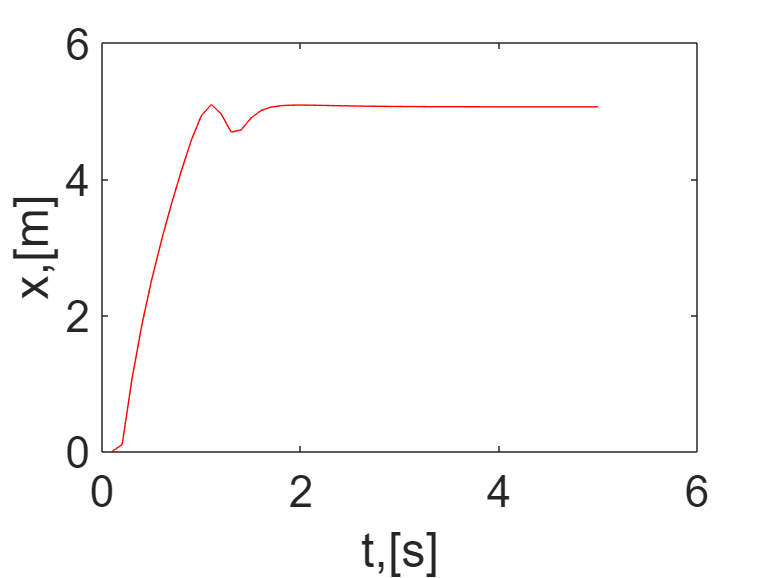


% plotting functions
figure
plot(time, x_pos(1,:),'r');
set(gca, 'fontsize',24)
xlabel('t,[s]');
ylabel('x,[m]');

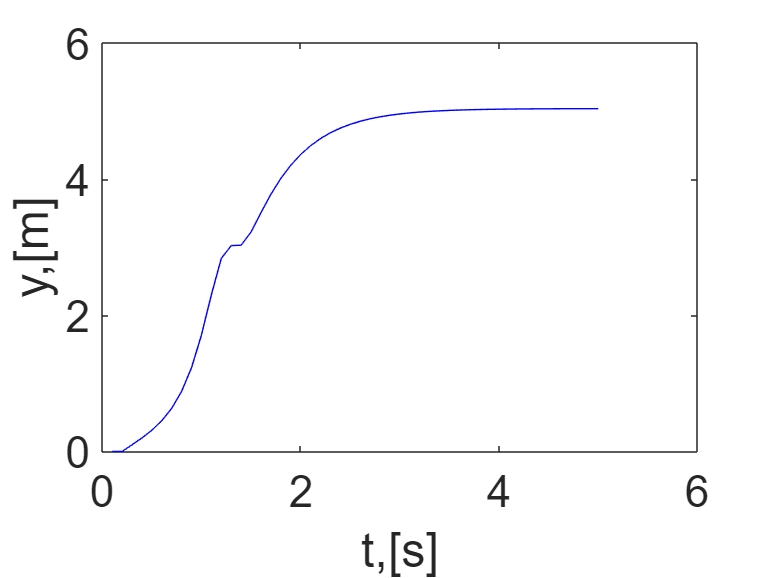


%
figure
plot(time, x_pos(2,:),'b-');
set(gca,'fontsize',24);
xlabel('t,[s]');
ylabel('y,[m]');

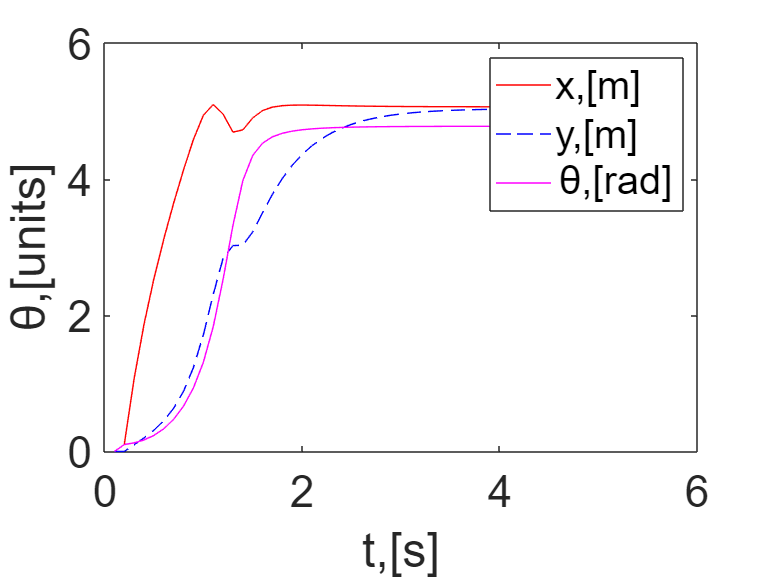


figure
plot(time, x_pos(1,:),'r');
hold on
plot(time, x_pos(2,:),'b--');
plot(time, x_pos(3,:),'m');
legend('x,[m]','y,[m]','\theta,[rad]');
set(gca,'fontsize',24)
xlabel('t,[s]');
ylabel('\theta,[units]');

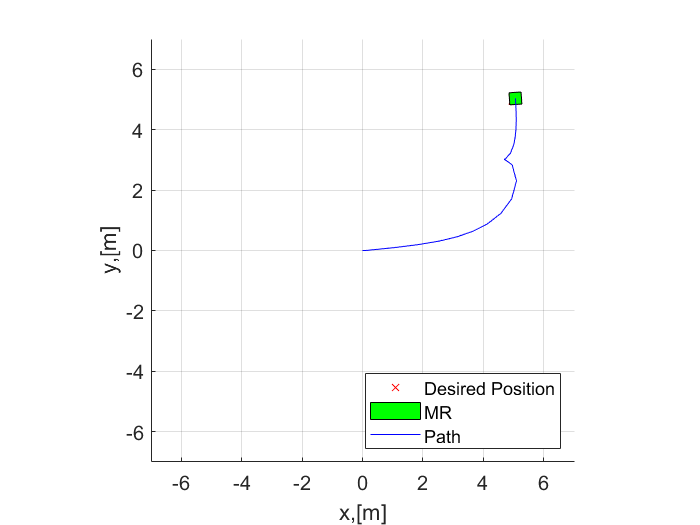


%% Animation (mobile robot motion animation)
l = 0.4; % length of the mobile robot
w = 0.4; % width of the mobile robot
% Mobile robot cooridinates
box_v = [-l/2,l/2,l/2,-l/2,-l/2;
         -w/2,-w/2,w/2,w/2,-w/2;];   
figure
for i = 1:5:length(time)
    theta = x_pos(3,i);
    R_theta = [cos(theta), -sin(theta);
             sin(theta), cos(theta);]; % rotation matrix
    v_pos = R_theta*box_v;
    scatter(position_r(1),position_r(2),69,"x","r")
    hold on, grid on
    fill(v_pos(1, :)+x_pos(1,i),v_pos(2,:)+x_pos(2,i),'g')
    hold on, grid on
    axis([-7 7 -7 7]), axis square
    plot(x_pos(1,1:i),x_pos(2,1:i),'b-');
    legend('Desired Position','MR','Path',"location","southeast")
    set(gca, 'fontsize',12)
    xlabel('x,[m]'); ylabel('y,[m]');
    pause(1)
    hold off
end % animation ends here